%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors      :-  Manas Kumar Mishra, Niranjana Vannadil 
% Project name :-  SEA (Statistical Enhancement of Audio)
% Organization :-  IIITDM Kancheepuram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Noisy clips
% 1. TempleNoisyclip1_Agra.mp3
% 2. TempleNoisyclip2_Agra.mp3
% 3. TempleNoisyclip1_Agra.wav
% 4. TempleNoisyclip2_Agra.wav
% 5. TestAudio4.wav
% 6. TestAudio5.wav

[samples, fsample] = audioread('TestSongs/TempleNoisyclip1_Agra.wav');

% player = audioplayer(samples, fsample);
% play(player);

fsample %sampling frequency of audio 

fsample = 44100

samples; %Samples, right and left channel

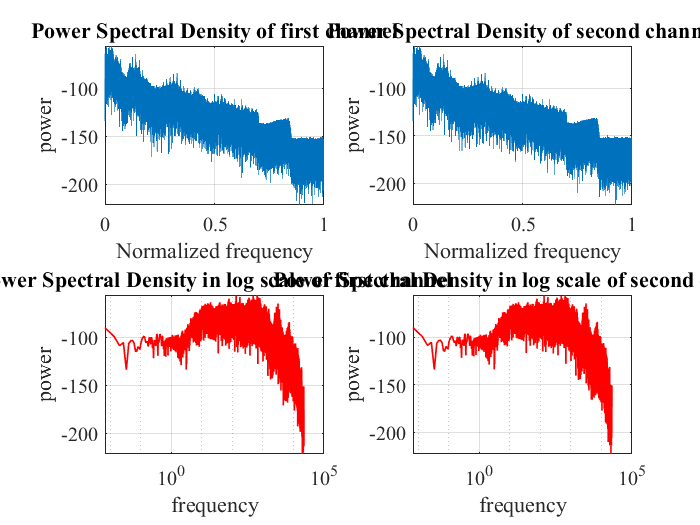

% PSD Show

ShowPSD(samples, fsample);

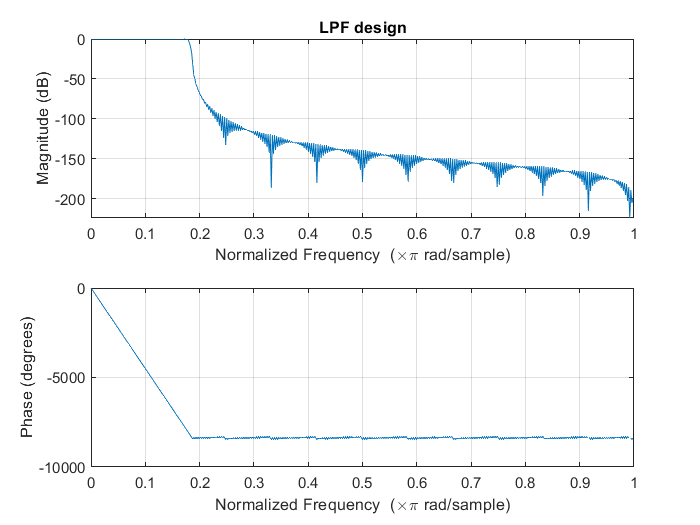

% Preprocessing step
Cutoff = 0.182;

filterLength =500;

filterCoff = impulseResponseOfFilterLPF(Cutoff, filterLength, 3);

NewSamples1 = myFIRFilter(samples(:, 1)', filterCoff);
NewSamples2 = myFIRFilter(samples(:, 2)', filterCoff);
NewSample = [NewSamples1', NewSamples2'];




player = audioplayer(NewSample, fsample);
play(player);


% PSD view
ShowPSD(NewSample, fsample);


% Output = MMSESTSA84(NewSample(:, 1), fsample);

The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440


% Output2 = MMSESTSA84(NewSample(:, 2), fsample);

The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440


% output = [Output, Output2]

output =    -0.0020    0.0019
   -0.0027    0.0003
   -0.0024   -0.0011
   -0.0014   -0.0023
    0.0003   -0.0032
    0.0022   -0.0036
    0.0042   -0.0035
    0.0057   -0.0031
    0.0067   -0.0022
    0.0068   -0.0012


player = audioplayer(output, fsample);
play(player);

% player = audioplayer(Output, fsample);
% play(player);
Output

Output =    -0.0038
   -0.0035
   -0.0033
   -0.0032
   -0.0032
   -0.0033
   -0.0035
   -0.0038
   -0.0041
   -0.0044


a= rand(1, 44100)

a =     0.8147    0.9058    0.1270    0.9134    0.6324    0.0975    0.2785    0.5469    0.9575    0.9649    0.1576    0.9706    0.9572    0.4854    0.8003    0.1419    0.4218    0.9157    0.7922    0.9595    0.6557    0.0357    0.8491    0.9340    0.6787    0.7577    0.7431    0.3922    0.6555    0.1712    0.7060    0.0318    0.2769    0.0462    0.0971    0.8235    0.6948    0.3171    0.9502    0.0344    0.4387    0.3816    0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094    0.7547



W= ceil(0.032*44100)

W = 1412

Window = hamming(W);
overlappPerc=0.75;
sp = 1-overlappPerc

sp = 0.2500


Window=Window(:);
% a1= NewSample(:, 1)';
L=length(a);

SP=fix(W.*sp);

N=fix((L-W)/SP +1); %number of segments

repmat(1:W, N, 1);
repmat((0:(N-1))'*SP,1,W);
Index=(repmat(1:W,N,1)+repmat((0:(N-1))'*SP,1,W))'

Index =            1         354         707        1060        1413        1766        2119        2472        2825        3178        3531        3884        4237        4590        4943        5296        5649        6002        6355        6708        7061        7414        7767        8120        8473        8826        9179        9532        9885       10238       10591       10944       11297       11650       12003       12356       12709       13062       13415       13768       14121       14474       14827       15180       15533       15886       16239       16592       16945       17298
           2         355         708        1061        1414        1767        2120        2473        2826        3179        3532        3885        4238        4591        4944        5297        5650        6003        6356        6709        7062        7415        7768        8121        8474        8827        9180        9533        9886       10239       10592       10945       

hw=repmat(Window,1,N);
Seg=a(Index);
Seg=a(Index).*hw;

Seg

Seg =     0.0652    0.0431    0.0530    0.0501    0.0414    0.0795    0.0454    0.0678    0.0724    0.0680    0.0075    0.0182    0.0121    0.0305    0.0592    0.0586    0.0373    0.0592    0.0063    0.0476    0.0099    0.0578    0.0060    0.0570    0.0598    0.0414    0.0722    0.0599    0.0482    0.0708    0.0664    0.0780    0.0109    0.0436    0.0299    0.0401    0.0239    0.0319    0.0045    0.0258    0.0693    0.0417    0.0116    0.0680    0.0443    0.0728    0.0028    0.0022    0.0297    0.0703
    0.0725    0.0559    0.0265    0.0110    0.0445    0.0684    0.0770    0.0544    0.0701    0.0270    0.0521    0.0568    0.0120    0.0061    0.0661    0.0776    0.0239    0.0711    0.0502    0.0553    0.0505    0.0107    0.0471    0.0661    0.0248    0.0015    0.0453    0.0381    0.0481    0.0519    0.0472    0.0336    0.0066    0.0066    0.0027    0.0082    0.0620    0.0645    0.0345    0.0747    0.0334    0.0630    0.0409    0.0395    0.0381    0.0095    0.0486    0.0122    0.0383   

% Framing of the sample values
conSampleLength = 0.032

conSampleLength = 0.0320

WinLen = ceil(conSampleLength*fsample);
overlappPerc = 0.75;

[frame1, frame2]= Framing(NewSample,WinLen, overlappPerc, 1);
% [FrameSize, NumOfFrame]=size(frame1)


Y=fft(frame1);
YPhase=angle(Y(1:fix(end),:)); %Noisy Speech Phase
Y=abs(Y(1:fix(end),:))%Specrogram

Y =     0.0009    0.1742    0.8366    0.6474    0.9420    0.1754    3.0669    3.1141    0.7717    5.0736    7.0935    7.1548    4.6457    2.5115    7.8438    6.6608    3.5572    3.7545    2.1065    6.3484    6.3875    1.2537    0.7002    1.2279    2.5518    3.4808    2.7511    0.8000    7.3904   10.6230    6.0466    1.2755   12.0028   14.4536    4.5390    8.8215   11.8301    3.1508    2.5515    3.5894   13.9066    6.1241    0.7714    0.5008   10.3778   15.3039   16.8235   11.7887    2.5748    4.5160
    0.0005    0.1539    0.7549    1.4945    1.8240    2.0762    3.0452    3.2200    2.0386    4.0150    3.6224    3.2205    4.7227    5.4437    5.5325    3.5947    1.6195    1.6430    6.4935   10.2731    9.0242    5.7062    4.6199    2.8155    4.6072    3.9519    1.5864    5.1385    9.8146    7.4898    2.3588    5.9852   13.5228    7.8719    8.2076   10.3685   11.1935    5.5414    2.8800    7.0523   17.0430   15.9017    9.3770    9.6645   15.2140    8.2450    9.7004   17.3212   10.6982   11


numberOfFrames=size(Y,2)

numberOfFrames = 9451

FrameSize=size(Y,1)

FrameSize = 1412

IS = 0.25;
SP = 0.25; %0.25
W = ceil(0.032*fsample)

W = 1412

NIS=fix((IS*fsample-W)/(SP*W) +1)%number of initial silence segments

NIS = 28


N=mean(Y(:,1:NIS)')'; %initial Noise Power Spectrum mean

LambdaD =mean((Y(:,1:NIS)').^2)';

alpha=0.98; %0.98

NoiseCounter=0;
NoiseLength=9;%This is a smoothing factor for the noise updating

G=ones(size(N));%Initial Gain used in calculation of the new xi

Gamma=G;

Gamma1p5=gamma(1.5); %Gamma function at 1.5
X=zeros(size(Y)); % Initialize X (memory allocation)

h=waitbar(0,'Wait...');

for i =1:numberOfFrames
    % Something
    if i<=NIS % If initial silence ignore VAD
        SpeechFlag=0;
        NoiseCounter=100;
    else % Else Do VAD
        [NoiseFlag, SpeechFlag, NoiseCounter, Dist]=vad(Y(:,i),N,NoiseCounter); %Magnitude Spectrum Distance VAD
    end
    
    if SpeechFlag==0 % If not Speech Update Noise Parameters
        N=(NoiseLength*N+Y(:,i))/(NoiseLength+1); %Update and smooth noise mean
        LambdaD=(NoiseLength*LambdaD+(Y(:,i).^2))./(1+NoiseLength); %Update and smooth noise variance
    end
    
     gammaNew=(Y(:,i).^2)./LambdaD; %A postiriori SNR
     
     xi=alpha*(G.^2).*Gamma+(1-alpha).*max(gammaNew-1,0); %Decision Directed Method for A Priori SNR
     
     Gamma=gammaNew;
     
     nu=Gamma.*xi./(1+xi); % A Function used in Calculation of Gain
     
     G=(Gamma1p5*sqrt(nu)./Gamma).*exp(-nu/2)...
        .*((1+nu).*besseli(0,nu/2) +nu.*besseli(1,nu/2)); %MMSE Gain
    
     Indx=find(isnan(G) | isinf(G));
     G(Indx)=xi(Indx)./(1+xi(Indx));
     
     X(:,i)=G.*Y(:,i); %Obtain the new Cleaned value
     
     waitbar(i/numberOfFrames,h,num2str(fix(100*i/numberOfFrames)));
     
end

close(h);

output=OverlapAdd2(X,YPhase,W,SP*W);

player = audioplayer(output, fsample);
play(player);

Out_Audio1 = SEA_MMSE(frame1, fsample);
Out_Audio2 = SEA_MMSE(frame2, fsample);


EnhanceAudio = [Out_Audio1, Out_Audio2];
player = audioplayer(EnhanceAudio, fsample);
play(player);


% Improvement of the STSA algorithm
Out_Audio1 = SEA_MMSE_Imp2(frame1, fsample);
Out_Audio2 = SEA_MMSE_Imp2(frame2, fsample);


EnhanceAudio = [Out_Audio1, Out_Audio2];
player = audioplayer(EnhanceAudio, fsample);
play(player);

% Improvement of the STSA algorithm
Out_Audio1 = SEA_MMSE_Imp3(frame1, fsample);
Out_Audio2 = SEA_MMSE_Imp3(frame2, fsample);

EnhanceAudio = [Out_Audio1, Out_Audio2];
player = audioplayer(EnhanceAudio, fsample);
play(player)

% pesqbin(samples, EnhanceAudio, fsample, 'wb')
% pesq2('TestSongs\TestAudio4.wav', 'EnhanceAudio\entest.wav')

Error using pesq2 (line 75)
pesq2.m: Unsupported sampling rate (44100 Hz).
Only sampling rates of 8000 Hz (for narrowband assessment)
and 16000 Hz (for wideband assessment) are supported.

audiowrite('EnhanceAudio\Enhance1_templeNoise1.wav', EnhanceAudio, fsample);


% Fourier transform of the framed part
% FSAMPLE1 = fft(frame1);
% FSAMPLE2 = fft(frame2);
% 


% F = FSAMPLE1(1:fix(end), :);

% Experiment 
% A = [1, 2, 3, 4;
%     2, 4, 5, 6;
%     7, 8, 9, 10;
%     11, 12, 13, 14];
% 
% F = A(1:fix(end))

F =      1     2     7    11     2     4     8    12     3     5     9    13     4     6    10    14


% Convert Matrix into row vector 
% F1 = FSAMPLE1(1:fix(end));
% F2 = FSAMPLE2(1:fix(end));
% 

% % Magnitude term of fft term
% F1_mag = abs(F1);
% F2_mag = abs(F2);
% 
% % Phase term of the signal
% F1_phase = angle(F1);
% F2_phase = angle(F2);
% 

% % Asumming lambda_d (noise  variance) as constant value
% 
% % InitSeg = 0.25;
% 
% %Noise Estimation
% Perio1 = periodogram(abs(FSAMPLE1));
% [N_PSD1,P1,alpha1,lambda_d1] = Noise_Estimation_Minimum_Statistics(Perio1);

lambd_d = 2.2880e-15

% 
% Perio2 = periodogram(abs(FSAMPLE2));
% [N_PSD2,P2,alpha2,lambda_d2] = Noise_Estimation_Minimum_Statistics(Perio2);

lambd_d = 1.6843e-15

% 

% InitSeg = 0.25;
% 
% NIS = ceil(InitSeg*FrameSize)

NIS = 353

% F1_mag(1:NIS)

ans =     0.0009    0.0005    0.0003    0.0014    0.0006    0.0011    0.0005    0.0009    0.0002    0.0002    0.0007    0.0006    0.0003    0.0005    0.0005    0.0005    0.0004    0.0001    0.0002    0.0003    0.0006    0.0007    0.0001    0.0007    0.0005    0.0003    0.0005    0.0001    0.0004    0.0001    0.0002    0.0002    0.0002    0.0004    0.0003    0.0005    0.0004    0.0004    0.0003    0.0003    0.0001    0.0002    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001


% N = mean(F1_mag(1:NIS)')

N = 1.0772e-04

% LambdaD=mean((F1_mag(1:NIS)').^2)'%initial Noise Power Spectrum variance

LambdaD = 4.3549e-08

% 
% 
% Alpha = 0.99;
% % AlphaVec = Alpha*ones(1, FrameSize)
% start = 1;
% stop = FrameSize;
% 
% GammaFunction = gamma(1.5);
% 
% Gain1 = ones(1, FrameSize);
% Gain2 = ones(1, FrameSize);
% 
% Gamma1 = Gain1;
% Gamma2 = Gain2;
% 
% NoiseCounter=0;
% NoiseLength=9;
% 
% CleanedAudio1 = zeros(size(F1_mag));
% CleanedAudio2 = zeros(size(F2_mag));
% h=waitbar(0,'Wait...');
% 
% for i = 1:NumOfFrame
%     % Something
%     if i<=NIS % If initial silence ignore VAD
%         SpeechFlag=0;
%         NoiseCounter=100;
%     else % Else Do VAD
%         [NoiseFlag, SpeechFlag, NoiseCounter, Dist]=vad(F1_mag(start:stop),N,NoiseCounter); %Magnitude Spectrum Distance VAD
%     end
%     
%     if SpeechFlag==0 % If not Speech Update Noise Parameters
%         N=(NoiseLength*N+F1_mag(start:stop))/(NoiseLength+1); %Update and smooth noise mean
%         LambdaD=(NoiseLength*LambdaD+(F1_mag(:,i).^2))./(1+NoiseLength); %Update and smooth noise variance
%     end
%     
%     gammaNew1 = (F1_mag(start:stop).^2)./LambdaD;
%     gammaNew2 = (F2_mag(start:stop).^2)./LambdaD;
%     
%     kssai1 =max(Alpha*(Gain1.^2).*Gamma1+(1-Alpha).*max(gammaNew1, 0), 0.00001);
%     kssai2 =max(Alpha*(Gain2.^2).*Gamma2+(1-Alpha).*max(gammaNew2, 0), 0.00001);
%     
%     Gamma1 = gammaNew1;
%     Gamma2 = gammaNew2;
%     
%     nu1 = Gamma1.*kssai1/(1+kssai1);
%     nu2 = Gamma2.*kssai2/(1+kssai2);
%     
%     Gain1 = ((GammaFunction*sqrt(nu1))./Gamma1).*exp(-nu1/2).*[(1+nu1).*besseli(0, nu1/2)+nu1.*besseli(1, nu1/2)];
%     Gain2 = ((GammaFunction*sqrt(nu2))./Gamma2).*exp(-nu2/2).*[(1+nu2).*besseli(0, nu2/2)+nu2.*besseli(1, nu2/2)];
%     
%     Indx1=find(isnan(Gain1) | isinf(Gain1));
%     Gain1(Indx1)=kssai1(Indx1)./(1+kssai1(Indx1));
%     
%     Indx2=find(isnan(Gain2) | isinf(Gain2));
%     Gain2(Indx2)=kssai2(Indx2)./(1+kssai2(Indx2));
%     
%     
%     CleanedAudio1(start:stop)=Gain1.*F1_mag(start:stop);
%     CleanedAudio2(start:stop)=Gain2.*F2_mag(start:stop);
%     
%     start = start+FrameSize;
%     stop  = stop+FrameSize;
%     
%     waitbar(i/NumOfFrame,h,num2str(fix(100*i/NumOfFrame)));
% end
% close(h);
% 

% % Test1 = rand(1,100)
% % test2 = zeros(1, 100)
% % 
% % Test1 = reshape(Test1, 10,10)
% % test2 = reshape(test2, 10, 10)
% % 
% % Recon = OverlapAdd2(Test1, test2, FrameSize, ceil(0.25*FrameSize));

% CleanedAudioMat1 = reshape(CleanedAudio1,FrameSize, NumOfFrame);
% CleanedAudioMat2 = reshape(CleanedAudio2, FrameSize, NumOfFrame);
% 
% F1_phaseMat = reshape(F1_phase, FrameSize, NumOfFrame);
% F2_phaseMat = reshape(F2_phase, FrameSize, NumOfFrame);
% 
% % testing with foreigner function
% Clean1 = OverlapAdd2(CleanedAudioMat1, F1_phaseMat, FrameSize, ceil(0.4*FrameSize));
% Clean2 = OverlapAdd2(CleanedAudioMat2, F2_phaseMat, FrameSize, ceil(0.4*FrameSize));
% ceil(0.4*FrameSize)

ans = 565

% 
% FinalAudio = [Clean1, Clean2];
% player = audioplayer(FinalAudio, fsample);
% play(player);

% Clean1

Clean1 = 	1.0e+06 *

    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000


% % audiowrite('TestSongs\testresult.wav', FinalAudio, fsample);

% output = MMSESTSA84(NewSample, fsample)

The shift length have to be an integer as it is the number of samples.
shift length is fixed to 440


output =    -0.0038
   -0.0035
   -0.0033
   -0.0032
   -0.0032
   -0.0033
   -0.0035
   -0.0038
   -0.0041
   -0.0044


% 

% player = audioplayer(output, fsample);
% play(player);

% audiowrite('TestSongs\testresult2.wav', output, fsample);

% NewSamples1 = myFIRFilter(FinalAudio(:, 1)', filterCoff);
% NewSamples2 = myFIRFilter(FinalAudio(:, 2)', filterCoff);
% NewSample = [NewSamples1', NewSamples2'];


% player = audioplayer(NewSample, fsample);
% play(player);


%Noise Estimation
% Perio1 = periodogram(abs(FSAMPLE1));
% [N_PSD1,P1,alpha1,lambda_d1] = Noise_Estimation_Minimum_Statistics(Perio1);

lambd_d = 0.1019

% 
% Perio2 = periodogram(abs(FSAMPLE2));
% [N_PSD2,P2,alpha2,lambda_d2] = Noise_Estimation_Minimum_Statistics(Perio2);

lambd_d = 0.2221